### System states


Xk = zeros(8,1);        

### Parameters

%% Initialzization
% vehicle parameters

vx = 15/3.6;

deltaf = 0.01;
vy = 0;
FxEst = zeros(4,1);
FyEst = zeros(4,1);
rho_v = ones(3,1);
Caf = 30000; % N/rad;
Car = 30000; % N/rad
l = 2.398;
lf = 1.2;
lr = l-lf; 
d = 1.45;

Iz = 1130;
m = 1046;

rw = 0.27; %
Iw = 0.9; % kgm^2

% Motor
tau_Mzx = 0.01;

r = Xk(1,1);

### Prediction horizon /Control horizon/ Sample time

Np = 5;  % prediction horizon
Nc = 3; % control horizon
Ts = 0.1; % sample time

### Reference

%% Preview information
T_prev_step = 0.025;
SampleRange = Ts/T_prev_step;

Rr_Prev = [1:100]';

% yaw rate reference , left turn
Rs = Rr_Prev(SampleRange:SampleRange:Np*SampleRange,1)*pi/180

Rs =     0.0698
    0.1396
    0.2094
    0.2793
    0.3491



Rs_zeros = zeros(Np,1);

## Model

deltaAxi = [0 -d/(2*rw) d/(2*rw)];
Axi =[-(d/2)*cos(deltaf)+lf*sin(deltaf), -(d/2), (d/2)*cos(deltaf)+lf*sin(deltaf), (d/2)];
Ayi = [(d/2)*sin(deltaf)+lf*cos(deltaf)  -lr -(d/2)*sin(deltaf)+lf*cos(deltaf) -lr];
kyi = diag([Caf Car Caf Car]);

buf1 = vy+lf*r;
buf2 = vy-lr*r;
Theta = [-lf/vx/(1+(buf1/vx))^2;
    lf/vx/(1+(buf2/vx))^2;
    -lf/vx/(1+(buf1/vx))^2;
    lf/vx/(1+(buf2/vx))^2];

Km = Ayi*kyi*Theta;


M_Fx = Axi*FxEst;
M_Fy = Ayi*FyEst;
Xk(3,1) = M_Fx;
Xk(4,1) = 0;


A = [0 0 1/Iz 1/Iz 0 0 0 0;
    -1 0 0 0 0 0 0 0 ;
    0 0 -1/tau_Mzx 0 0 0 0 0;
    Km*[0 0 1/Iz 1/Iz 0 0 0 0];
    0 0 -d/(2*Iz*rw) -d/(2*Iz*rw) 0 0 0 0;
    0 0 -d/(2*Iz*rw) -d/(2*Iz*rw) 0 0 0 0;
    0 0 d/(2*Iz*rw) d/(2*Iz*rw) 0 0 0 0;
    0 0 d/(2*Iz*rw) d/(2*Iz*rw) 0 0 0 0]

A =          0         0    0.0009    0.0009         0         0         0         0
   -1.0000         0         0         0         0         0         0         0
         0         0 -100.0000         0         0         0         0         0
         0         0  -36.6694  -36.6694         0         0         0         0
         0         0   -0.0024   -0.0024         0         0         0         0
         0         0   -0.0024   -0.0024         0         0         0         0
         0         0    0.0024    0.0024         0         0         0         0
         0         0    0.0024    0.0024         0         0         0         0


B = [0 -d/(2*Iz*rw) d/(2*Iz*rw);
    zeros(2,3);
    Km*[0 -d/(2*Iz*rw) d/(2*Iz*rw)];
    -1/Iw d^2/(4*Iz*rw^2) -d^2/(4*Iz*rw^2);
    d^2/(4*Iz*rw^2) -1/Iw+d^2/(4*Iz*rw^2) -d^2/(4*Iz*rw^2);
    -1/Iw -d^2/(4*Iz*rw^2)  d^2/(4*Iz*rw^2);  
      -d^2/(4*Iz*rw^2) d^2/(4*Iz*rw^2) -1/Iw+d^2/(4*Iz*rw^2)]

B =          0   -0.0024    0.0024
         0         0         0
         0         0         0
         0   98.4641  -98.4641
   -1.1111    0.0064   -0.0064
    0.0064   -1.1047   -0.0064
   -1.1111   -0.0064    0.0064
   -0.0064    0.0064   -1.1047


% discretization
Ad = eye(8) + Ts*A

Ad =     1.0000         0    0.0001    0.0001         0         0         0         0
   -0.1000    1.0000         0         0         0         0         0         0
         0         0   -9.0000         0         0         0         0         0
         0         0   -3.6669   -2.6669         0         0         0         0
         0         0   -0.0002   -0.0002    1.0000         0         0         0
         0         0   -0.0002   -0.0002         0    1.0000         0         0
         0         0    0.0002    0.0002         0         0    1.0000         0
         0         0    0.0002    0.0002         0         0         0    1.0000


Bd = Ts*B

Bd =          0   -0.0002    0.0002
         0         0         0
         0         0         0
         0    9.8464   -9.8464
   -0.1111    0.0006   -0.0006
    0.0006   -0.1105   -0.0006
   -0.1111   -0.0006    0.0006
   -0.0006    0.0006   -0.1105



% output matrix
H= [1 zeros(1,7)]  % yaw rate

H =      1     0     0     0     0     0     0     0


phi = Ad;
gamma = Bd;

## 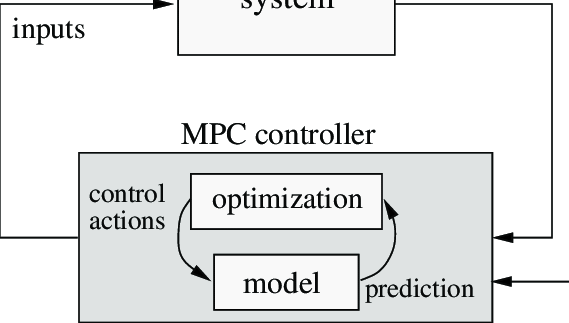

## Prediction model

% MPC initialization
NInp = 3;
NState = 8;

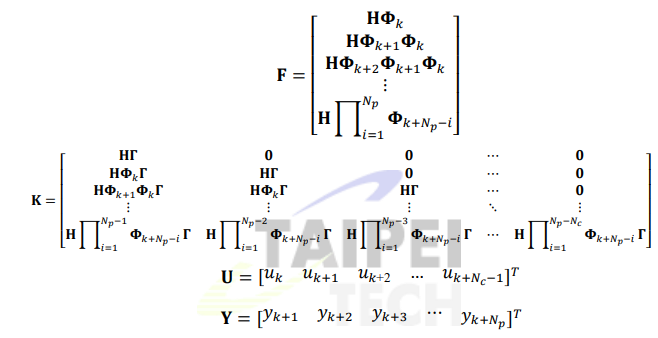

F = zeros(Np,NState);
% F1 = zeros(Np,wr);
K = zeros(Np,Nc*NInp);
% K1 = zeros(Np,Nc*NInp);

% yaw rate
buff = zeros(Np,NInp);
for j = 1:Np
    F(j,1:NState)=H*phi^j;
    buff(j,1:NInp) = H*(phi^(j-1))*gamma;
end

for i = 1:Nc
    K(i:Np,(1+(NInp)*(i-1):NInp*i)) = buff(1:Np+1-i,:);
end

F

F =     1.0000         0    0.0001    0.0001         0         0         0         0
    1.0000         0   -0.0010   -0.0001         0         0         0         0
    1.0000         0    0.0099    0.0005         0         0         0         0
    1.0000         0   -0.0910   -0.0012         0         0         0         0
    1.0000         0    0.8232    0.0033         0         0         0         0


K

K =          0   -0.0002    0.0002         0         0         0         0         0         0
         0    0.0006   -0.0006         0   -0.0002    0.0002         0         0         0
         0   -0.0017    0.0017         0    0.0006   -0.0006         0   -0.0002    0.0002
         0    0.0045   -0.0045         0   -0.0017    0.0017         0    0.0006   -0.0006
         0   -0.0120    0.0120         0    0.0045   -0.0045         0   -0.0017    0.0017


### Constraints

*ignore this section first

%% MPC constraints
C1 = ones(Nc,1);
C2 = tril(ones(Nc));
% amplitude constraint on control signal
umin = [-300;
    -160;
    -160];
umax = [300;
    160;
    160];
Umin = repmat(umin,Nc,1);
Umax = repmat(umax,Nc,1);


M2=[-eye(Nc*NInp); eye(Nc*NInp)];
N2 = [-Umin; Umax];

A_cons = M2

A_cons =     -1     0     0     0     0     0     0     0     0
     0    -1     0     0     0     0     0     0     0
     0     0    -1     0     0     0     0     0     0
     0     0     0    -1     0     0     0     0     0
     0     0     0     0    -1     0     0     0     0
     0     0     0     0     0    -1     0     0     0
     0     0     0     0     0     0    -1     0     0
     0     0     0     0     0     0     0    -1     0
     0     0     0     0     0     0     0     0    -1
     1     0     0     0     0     0     0     0     0


b_cons = N2

b_cons =    300
   160
   160
   300
   160
   160
   300
   160
   160
   300


### Weighting

%% Command calculation
r_max = 1*pi/180;
beta_max = 10*pi/180;
Trq_max = 100;


w_r = 1/r_max^2;
w_beta = 1/beta_max^2;
w_tm = 1/Trq_max^2;

W_WLR = diag(repmat(rho_v',1,Nc));


% error weighting
Q = w_r*eye(Np)

Q = 1.0e+03 *

    3.2828         0         0         0         0
         0    3.2828         0         0         0
         0         0    3.2828         0         0
         0         0         0    3.2828         0
         0         0         0         0    3.2828


R_bar = w_tm*(W_WLR)

R_bar = 1.0e-04 *

    1.0000         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0         0
         0         0         0    1.0000         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0
         0         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0         0         0    1.0000


### Control action

Global minimum

u_op = inv( ((K')*Q*K+R_bar) )*(K')*Q*(Rs-F*Xk) % not satisfy constraints

u_op =          0
  -30.3208
   30.3208
         0
 -150.6858
  150.6858
         0
 -254.8462
  254.8462


### Quadratic programming form

Transfrom problem to QP

H_qp =  (K')*Q*K + R_bar;
H_qp = (H_qp+H_qp')/2;
f_qp = -(K')*Q*(Rs-F*Xk);

u = -H_qp\f_qp % Solution should be identical to u_op

u =          0
  -30.3208
   30.3208
         0
 -150.6858
  150.6858
         0
 -254.8462
  254.8462


u_star = u(1:3,1) % Actual control command being used

u_star =          0
  -30.3208
   30.3208


MzRef = ( -u_star(2,1) + u_star(3,1) )*d/(2*rw) % Yaw moment

MzRef = 162.8338

### Constraint command

x = quadprog(H_qp,f_qp,A_cons,b_cons) % satisfy constraints


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =          0
  -38.3238
   38.3238
         0
 -136.5597
  136.5597
         0
 -160.0000
  160.0000
